[y,fs] = audioread('Original_Clip.mp3')

y =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 48000

y = y(:,1);
N = length(y);
t = (0:N-1)/fs ;
N/fs

ans = 234.3490

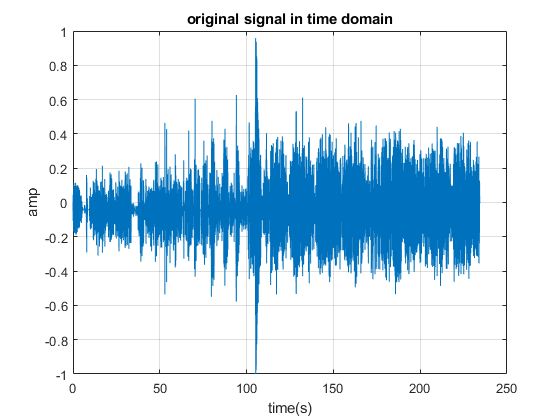

plot(t,y)
grid on
xlabel('time(s)') ;
ylabel ('amp') ;
title ('original signal in time domain') ;

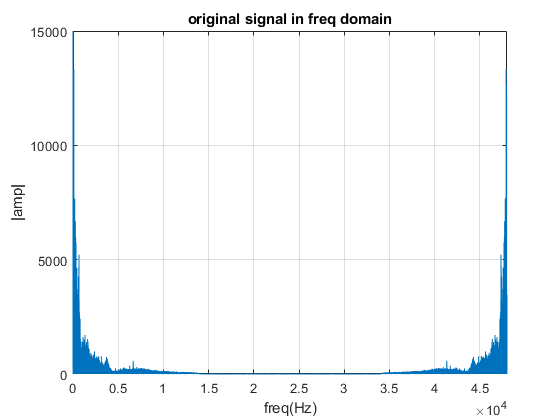


Y = fft(y) ;
f = linspace(0,fs,N);
plot(f,abs(Y))
ylim([0,15000]) ;
xlim([0,fs]) ;
grid on
xlabel('freq(Hz)') ;
ylabel ('|amp|') ;

title ('original signal in freq domain') ;

[y1,fs] = audioread('vuvuzela.wav')

y1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 22050

y1 = y1(:,1);
N = length(y1);
t = (0:N-1)/fs ;
N/fs

ans = 193.3584

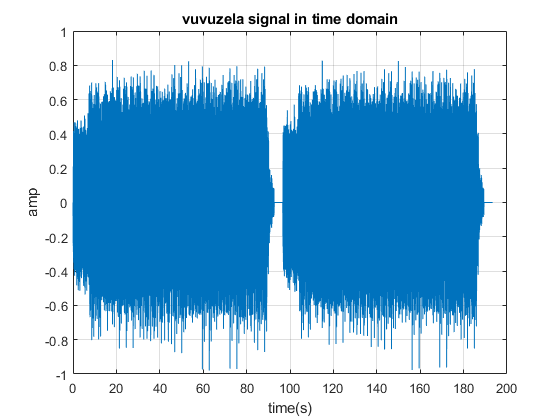

plot(t,y1)
grid on
xlabel('time(s)') ;
ylabel ('amp') ;
title ('vuvuzela signal in time domain') ;

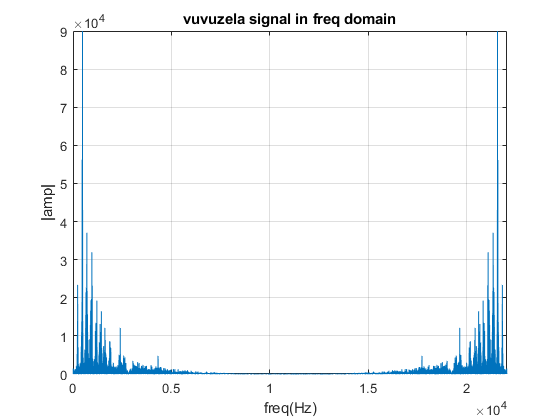


Y1 = fft(y1) ;
f = linspace(0,fs,N);
plot(f,abs(Y1))
ylim([0,90000]) ;
xlim([0,fs]) ;
grid on
xlabel('freq(Hz)') ;
ylabel ('|amp|') ;
title ('vuvuzela signal in freq domain') ;

[x,fs] = audioread('Distorted_Clip.mp3')

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 48000

x = x(:,1);
N = length(x);
t = (0:N-1)/fs ;
N/fs

ans = 225.7090

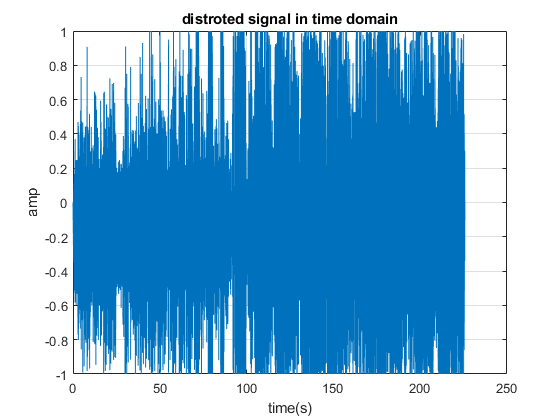

plot(t,x)
grid on
xlabel('time(s)')
ylabel ('amp')
title ('distroted signal in time domain')

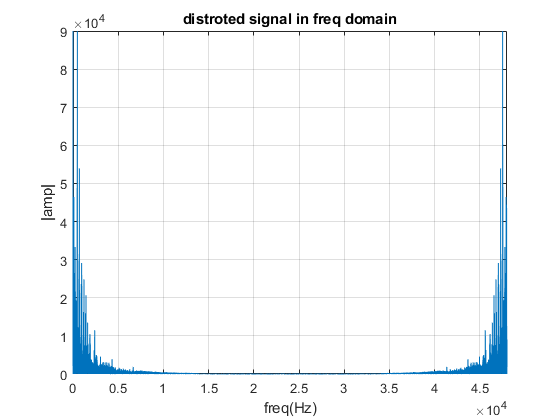


X = fft(x) ;
f = linspace(0,fs,N);
plot(f,abs(X))
ylim([0,90000]) ;
xlim([0,fs]) ;
grid on
xlabel('freq(Hz)') ;
ylabel ('|amp|') ;
title ('distroted signal in freq domain') ;

%p=audioplayer(x,fs) ;
%play(p) ;

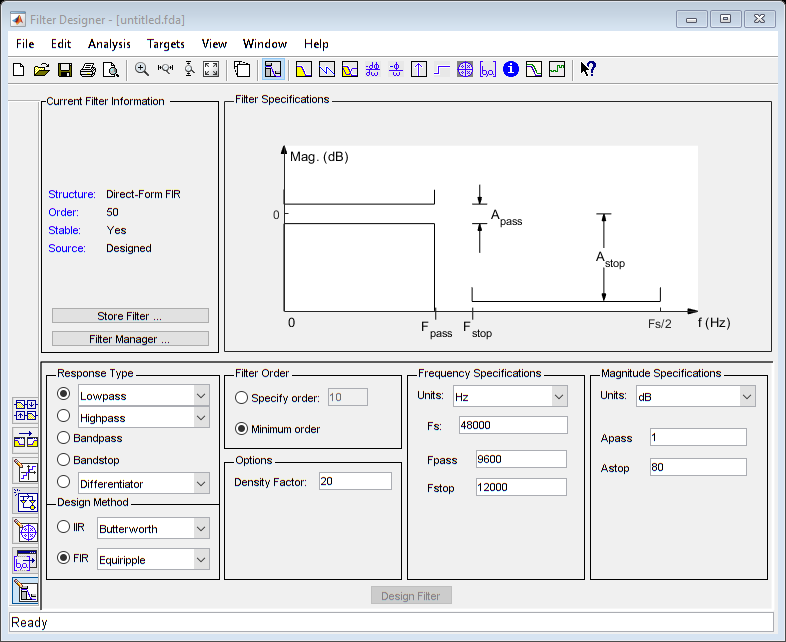

filterDesigner

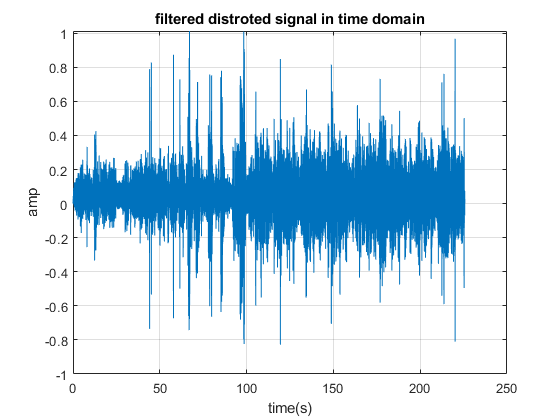

filterSignal = filter(Hd , x) ;
filterSignalTransform = fft(filterSignal) ;
plot(t,filterSignal)
grid on
xlabel('time(s)');
ylabel ('amp');
title ('filtered distroted signal in time domain');

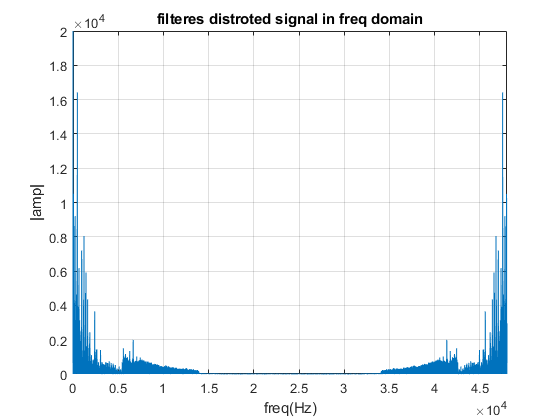


plot(f,abs(filterSignalTransform))
ylim([0,20000]) ;
xlim([0,fs]) ;
grid on
xlabel('freq(Hz)') ;
ylabel ('|amp|') ;
title ('filteres distroted signal in freq domain') ;

p=audioplayer(filterSignal,fs) ;
play(p) ;